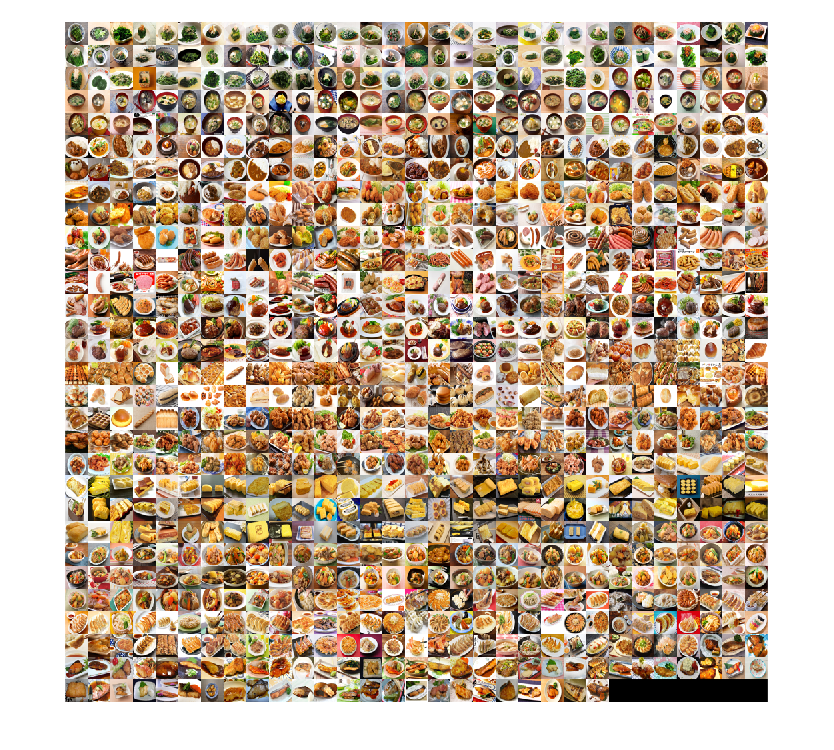

%学習イメージの取得
food_ds = imageDatastore('/Users/mizuno/Documents/MATLAB/deep01/image','IncludeSubfolders',true,'LabelSource','foldernames','ReadFcn',@imageread);
[trainImgs,testImgs] = splitEachLabel(food_ds,0.8);
numClasses = numel(categories(food_ds.Labels));
%montage(food_ds)

%AlexNet の変更によるネットワークの作成
net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;

%学習アルゴリズム オプションの設定
options = trainingOptions('sgdm','InitialLearnRate', 0.001);

%学習の実行
[foodnet,info] = trainNetwork(trainImgs, layers, options);

Training on single CPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |        7.03% |       3.2057 |          0.0010 |
|      10 |          50 |       00:08:55 |       97.66% |       0.0921 |          0.0010 |
|      20 |         100 |       00:17:49 |      100.00% |       0.0240 |          0.0010 |
|      30 |         150 |       00:26:43 |      100.00% |       0.0045 |          0.0010 |
|========================================================================================|


%info の TrainingLoss フィールドに格納されている学習損失をプロットしてください。
plot(info.TrainingLoss)

%学習済みネットワークを使用したテスト イメージの分類
foodpreds = classify(foodnet,testImgs);

%関数 nnz と等号演算子 (==) を使用して、正しい分類と一致している予測された分類の数をカウント
numCorrect = nnz(foodpreds == testImgs.Labels)

numCorrect = 142

foodCorrect = numCorrect / numel(foodpreds)

foodCorrect = 0.7717

[foodconf, foodnames] = confusionmat(testImgs.Labels, foodpreds)

foodconf =     17     0     0     0     0     0     0     0     0     0     0     0
     0    12     0     0     1     0     0     0     0     0     0     0
     0     0    11     0     0     1     0     0     0     2     0     0
     0     0     0    11     1     0     0     2     0     0     0     0
     0     0     0     1    10     2     1     1     0     1     0     0
     0     0     1     2     0    12     0     0     0     1     0     0
     0     0     0     0     1     0    13     0     1     0     0     0
     1     0     0     1     2     2     1     9     0     0     0     1
     0     0     0     0     0     0     0     0    15     0     3     0
     0     0     0     0     0     0     0     1     0    15     0     0


foodnames = 12×1 categorical array
     ほうれん草のおひたし 
     みそ汁 
     カレー 
     コロッケ 
     ソーセージ 
     ハンバーグ 
     パン 
     唐揚げ 
     玉子焼き 
     肉じゃが 
     餃子 
     魚の照り焼き 


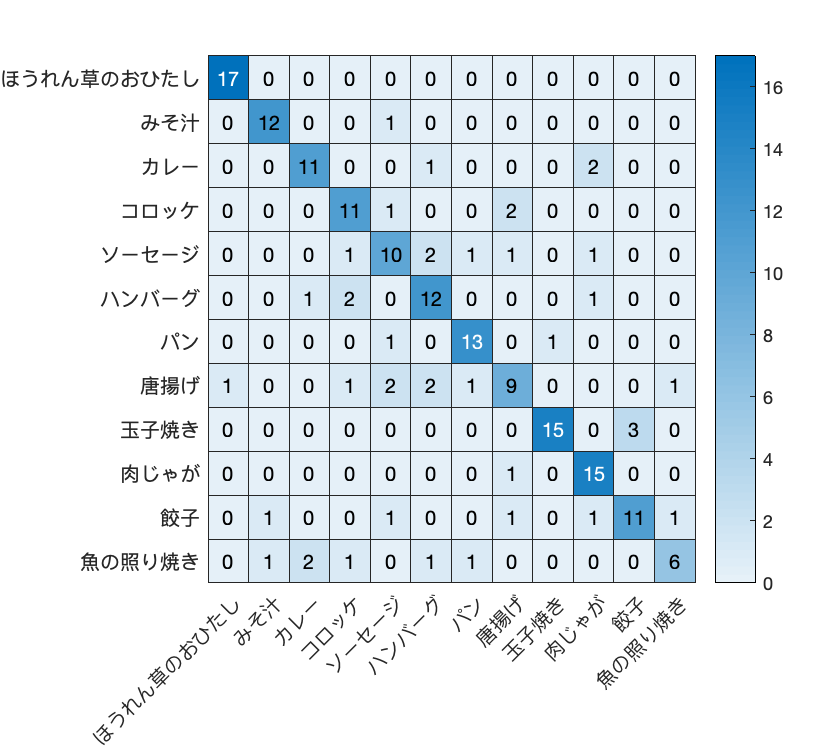

ans =   HeatmapChart with properties:

        XData: {12×1 cell}
        YData: {12×1 cell}
    ColorData: [12×12 double]

  Show all properties


heatmap(foodnames, foodnames, foodconf)

function img = imageread(file)
    img = imread(file);
    img = imresize(img,[227 227]);
end